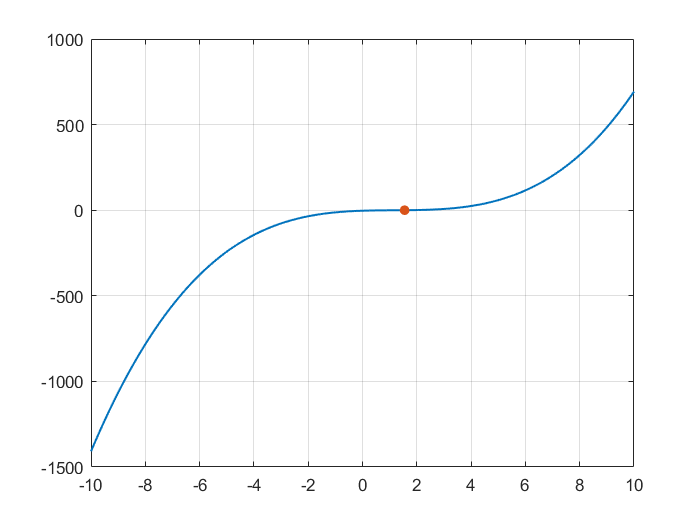

    %1
x = -10:0.01:10;
y = x.^3 - 3.55.*x.^2+5.1.*x-3.1;
yP = [1 -3.55 5.1 -3.1];
plot(x, y, 'LineWidth', 1.2);
hold on;
R = roots(yP);
L = real(R) == R;
R = R(L);
plot(R, 0, '.', 'MarkerSize', 20);
grid on;
hold off

%3
yP = [2 -3 4 -5 6];
yD = [1 -3 1];
[q,r] = deconv(yP, yD);
disp(q);

     2     3    11



yW = [1 -3 -1 -1];
yB = [3 -2 1];
[q_1,r_1] = deconv(yW, yB);
disp(q_1);

    0.3333   -0.7778



%4
%реализация схемы горнера для любого полинома
n = input("степень полинома = ");
x_0 = input("точка = ");
a_0 = input('a0 = ');
b=a_0;
while n~=0
    a = input('a=');
    b = b.*x_0 + a;
    n=n-1;
end
disp(b);

        1364




P = [1 -2 6 -10 16];
polyder(P);
Q = [1 1+2i 0 -1-3i 0 7];
polyder(Q);
%затем ввести значение в алгоритм в начале программы

%6
P = [1 0 0];
Q = [1 4 1 -6];
[r, s, K] = residue(P, Q)

r =     2.2500
   -1.3333
    0.0833


s =    -3.0000
   -2.0000
    1.0000



K =

     []



P_2 = [1 3];
Q_2 = [1 -1 1 -1];
[r_1, s_1, K_1] = residue(P_2, Q_2)

r_1 =    2.0000 + 0.0000i
  -1.0000 + 0.5000i
  -1.0000 - 0.5000i


s_1 =    1.0000 + 0.0000i
   0.0000 + 1.0000i
   0.0000 - 1.0000i



K_1 =

     []



P_3 = [1 0 0];
Q_3 = [1 0 0 0 -1];
[r_2, s_2, K_2] = residue(P_3, Q_3)

r_2 =   -0.2500 + 0.0000i
   0.2500 + 0.0000i
   0.0000 - 0.2500i
   0.0000 + 0.2500i


s_2 =   -1.0000 + 0.0000i
   1.0000 + 0.0000i
   0.0000 + 1.0000i
   0.0000 - 1.0000i



K_2 =

     []



%7
n=input("n = ");
x = [1:1:n]

x =      1     2     3     4


y = [1./(1:1:n) ]

y =     1.0000    0.5000    0.3333    0.2500


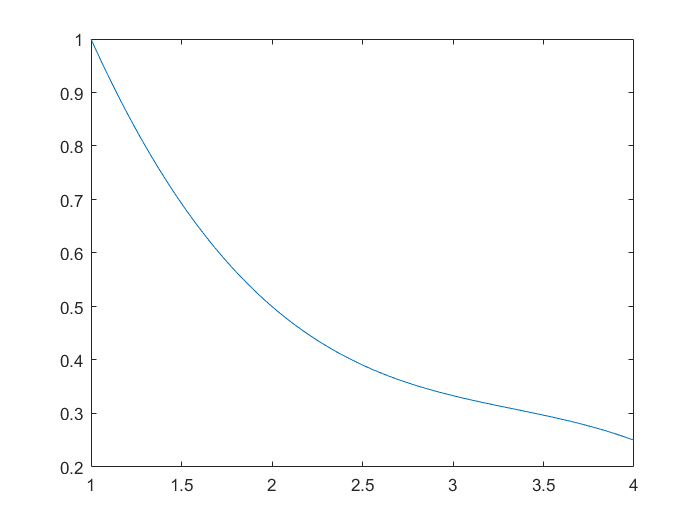

X = 1:0.01:n;
Y = interp1(x, y, X, 'spline' );
plot(X, Y);
hold on
I = find(Y==0);
plot(X(I), Y(I), '.r', 'MarkerSize' , 20);
hold off

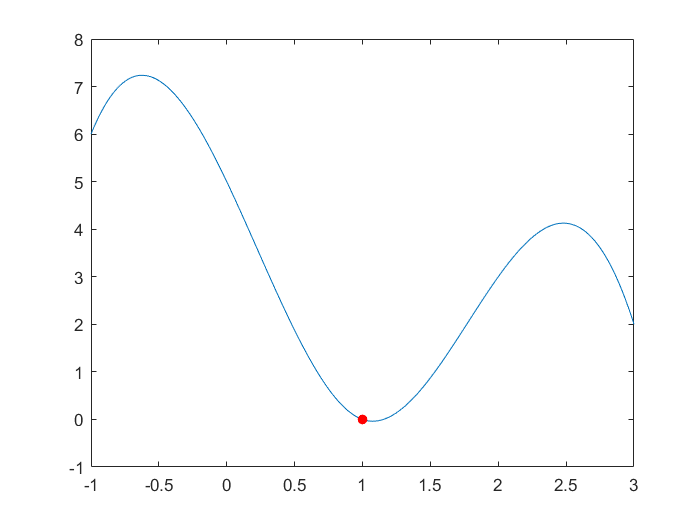


x = [-1 0 1 2 3];
y = [6 5 0 3 2];
X = -1:0.01:3;
Y = interp1(x, y, X, 'spline' );
plot(X, Y);
hold on
I = find(Y==0);
plot(X(I), Y(I), '.r', 'MarkerSize' , 20);
hold off

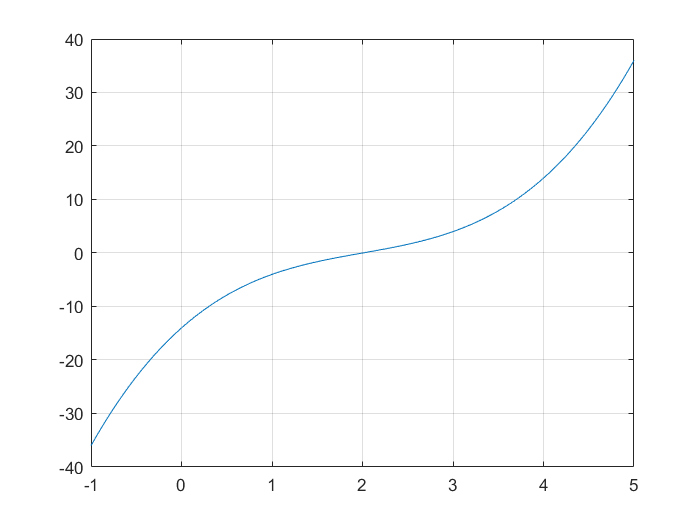

%8
P = [1 -6 15 -14];
r = roots(P);
x = linspace(-1,5,100);
F = polyval(P,x);
plot(x, F);
grid on

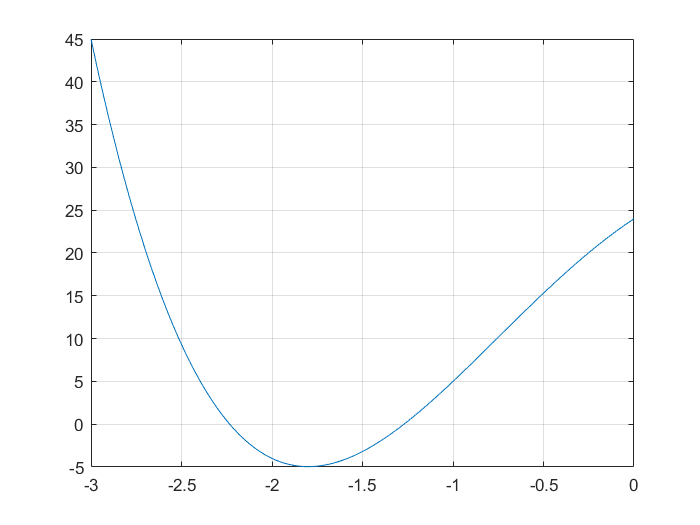


Q = [1 -2 -8 14 24];
r_2 = roots(Q);
x = linspace(-3,0,100);
F_2 = polyval(Q,x);
plot(x, F_2);
grid on

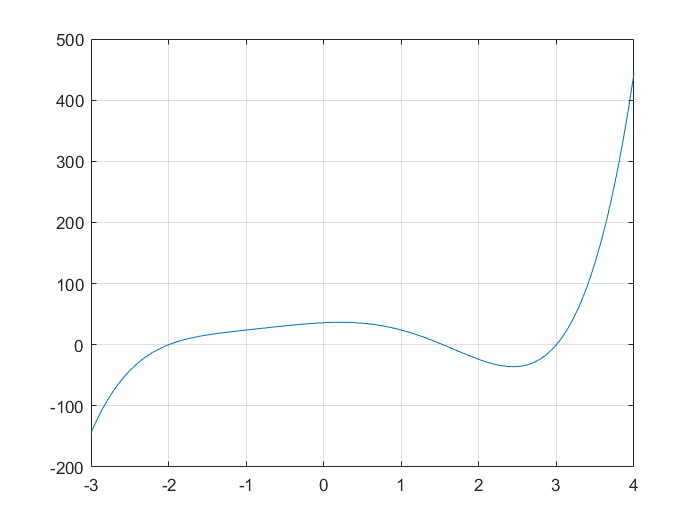


T = [1 0 -7 -12 6 36];
r_3 = roots(T);
x = linspace(-3,4,100);
F_3 = polyval(T,x);
plot(x, F_3);
grid on

%10
syms x;
[G, S, T] = gcd(x.^4 + 2.*x.^3 - x.^2 - 4.*x - 2, x.^4 + x.^3 - x.^2 - 2.*x -2)

$$G = x^{2}-2$$

$$S = -x-1$$

$$T = x+2$$

[G_1, S_1, T_1] = gcd(4.*x.^4 - 2.*x.^3 - 16.*x.^2 + 5.*x + 9, 2.*x.^3 - x.^2 - 5.*x + 4)

$$G\_1 = x-1$$

$$S\_1 = \frac{1}{3}-\frac{x}{3}$$

$$T\_1 = \frac{2\,x^{2}}{3}-\frac{2\,x}{3}-1$$

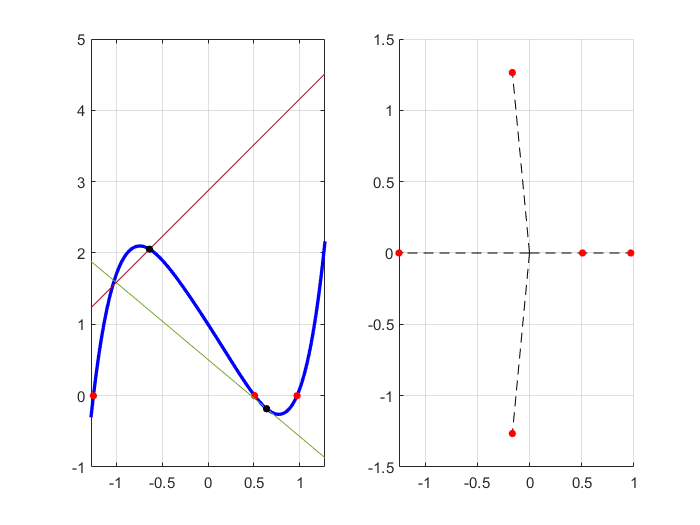

%2
P = [1 0.1 0.2 -0.2 -2 1];
R = roots(P);
    Real = R(real(R) == R);
    Max = max(abs(R));
X = -Max:0.01:Max;
Y = X.^5+0.1.*X.^4+0.2.*X.^3-0.2.*X.^2-2.*X+1;
    subplot(1, 2, 1);
    plot(X,Y, 'b', 'LineWidth', 2);
    hold on;
    plot(Real, 0, '.r', 'MarkerSize', 15);
x_1 = 1/2*Max;
y_1 = polyval(P, x_1);
D = polyder(P);
k_1 = polyval(D, x_1);
K = k_1*(X-x_1)+y_1;
    plot(X, K);
    plot(x_1, y_1, '.k', 'MarkerSize', 15);
x_2 = -1/2*Max;
y_2 = polyval(P, x_2);
k_2 = -1/polyval(D, x_2);
N = k_2*(X-x_2)+y_2;
ang = atan(k_2);
x_n = cos(ang)+x_2;
y_n = sin(ang)+y_2;
    line([x_2 x_n], [y_2 y_n], 'Color', 'Red');
    plot(X, N);
    plot(x_2, y_2, '.k', 'MarkerSize', 15);
    grid on
    hold off
    subplot(1, 2, 2)
Re = real(R);
Im = imag(R);
hold on
for i = 1:size(R)
    plot([0 Re(i)], [0 Im(i)], 'k--');
end
    plot(Re, Im, '.r', 'MarkerSize', 15);
    grid on
    hold off